# Sistemas de segundo orden

No podemos resolver fácilmente un sistema de ecuaciones diferenciales de orden superior, por lo que aquí viene nuestra herramienta favorita desde segundo semestre, la serie de Taylor. Para resolver una ecuación de este tipo, tenemos que linealizarla, sobre todo por términos como senos o cosenos.

% simbolica
syms theta(t) g l theta0

Dtheta = diff(theta);
eqn = diff(theta, t, 2) + (g/l)*theta == 0;
cond1 = theta(0) == theta0;
cond2 = Dtheta(0) == 0;
cond = [cond1 cond2];

thetaSolP = dsolve(eqn, cond)

$$thetaSolP = \frac{\theta_{0}\,{\mathrm{e}}^{-\frac{t\,\sqrt{-g\,l}}{l}}\,\left({\mathrm{e}}^{\frac{2\,t\,\sqrt{-g\,l}}{l}}+1\right)}{2}$$

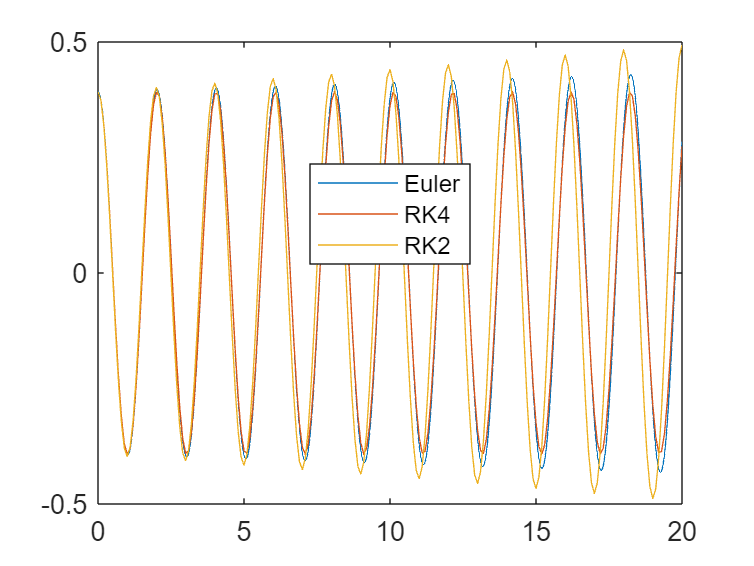


% numerica
g = 9.81; l = 1;
f = @(t, y) [y(2); -(g/l)*sin(y(1))];
y0 = [pi/8; 0];
tspan = [0 20];

[t, y] = odeEuler(f, y0, tspan, 0.001);
plot(t, y(1, :))
hold on
[t, y] = odeRK4(f, y0, tspan, 0.1);
plot(t, y(1, :))
[t, y] = odeRK2(f, y0, tspan, 0.1, 3/4);
plot(t, y(1, :))

legend('Euler', 'RK4', 'RK2', 'location', 'best')
hold off

## Problema de los tres resortes y las dos masas


f = @(t, x) [(-k1*x(1) - k2*(x(1) - x(2)))/m1; (-k2*(x(2) -x(1)) - k3*x(2))/m2];